%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% TF of 2nd-Type 2nd-Order ChargePump PLL                          %
% 2nd-Order prop-Integrator filter                                 %
%    CP-------------VCO           ---Icp/2pi--F(s)--Kv--           %
%        |                        |                   |           %
%        R1                       |--------1/N--------|           %
%        |                                                        %
%        C1                                                       %
%        |                                                        %
%       GND                                                       %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc; clearvars;
fref_num=1/3.7e-9;
fstart=1e4; fstop=fref_num; NumPerDec=21;
freq=LogDistrib(fstart,fstop,NumPerDec);
freq_rad_norm=freq/fref_num*2*pi;

% vco curve fitting parameter: f=a*exp(b*x)+c*exp(d*x), x=0-1023
a=4.7848e8;
b=1.7776e-4;
c=2.167e7;
d=1.735e-3;

syms Kp Ki Kv N z sigma fref td
Z1=Kp+Ki*1/(z-1);
Fs=Z1;
Kdco=Kv/fref;                   % UI/LSB
td=z^-2;                         % 
Kd=0.399/sigma;                 % 1/UI
Gs=Kd*Fs*Kdco/(z-1)/N*td;       % loop TF
Hs=N*Gs/(1+Gs);                 % closed loop TF
K=Kd*Kp*Kdco*1/N;               % Loop gain, normalized z freq.
K1=K/2/pi*fref;

fprintf('Proportional-Integrational Filter TF:\n');

Proportional-Integrational Filter TF:


pretty(simplifyFraction(Fs)); %fprintf('\n');

Ki - Kp + Kp z
--------------
     z - 1



fprintf('Open Loop TF G(s):\n');

Open Loop TF G(s):


pretty(simplifyFraction(Gs)); %fprintf('\n');

 399 Kv (Ki - Kp + Kp z)
-------------------------
               2        2
1000 N fref σ z  (z - 1)



fprintf('Open Loop Gain K:\n');

Open Loop Gain K:


pretty(simplifyFraction(K));  %fprintf('\n');

  399 Kp Kv
-------------
1000 N fref σ



fprintf('Closed loop TF H(s):\n');

Closed loop TF H(s):


pretty(simplifyFraction(Hs));

                                  399 Kv N (Ki - Kp + Kp z)
--------------------------------------------------------------------------------------------
               4                  3                  2
1000 N fref σ z  - 2000 N fref σ z  + 1000 N fref σ z  + 399 Kp Kv z + 399 Ki Kv - 399 Kp Kv



%fprintf('\n');
%pretty(simplifyFraction(diff(Hs,s)));

sigma_num=20e-3;          % sec
Kp_num=1;                 % 
Ki_num=2^-10;              % 
f0=630e6;                 % VCO free running freq.Hz
Kv_num=500e3;             % VCO gain，Hz/LSB
N_num=10;           

Gs=subs(Gs, [sigma, Kp, Ki, fref, Kv, N], [sigma_num, Kp_num, Ki_num, fref_num, Kv_num, N_num]);
Hs=subs(Hs, [sigma, Kp, Ki, fref, Kv, N], [sigma_num, Kp_num, Ki_num, fref_num, Kv_num, N_num]);
K =subs(K,  [sigma, Kp, Ki, fref, Kv, N], [sigma_num, Kp_num, Ki_num, fref_num, Kv_num, N_num]);


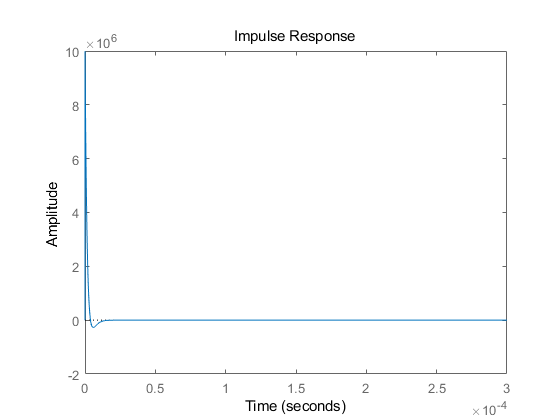

% time-domain response calc
Tresp=300e-6;                           %impulse response time
[num,den]=numden(Hs);
coef_n=double(fliplr(coeffs(num)));
coef_d=double(fliplr(coeffs(den)));
Hs_real=tf(coef_n,coef_d,1/fref_num);
impulse(Hs_real,Tresp)

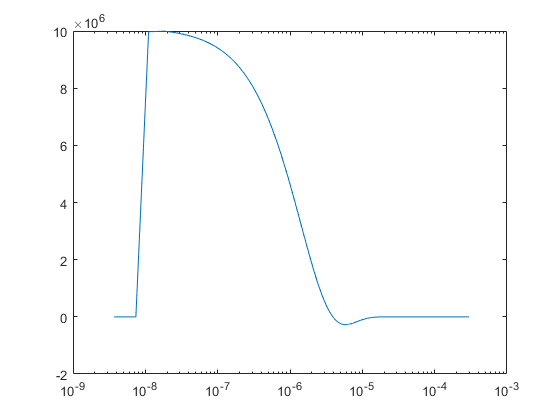

[impy,impt]=impulse(Hs_real,Tresp);
semilogx(impt,impy)

Tsettle=impt(find(abs(impy)>0.05,1,'last')) % settling time when error<5%

Tsettle = 3.9416e-05

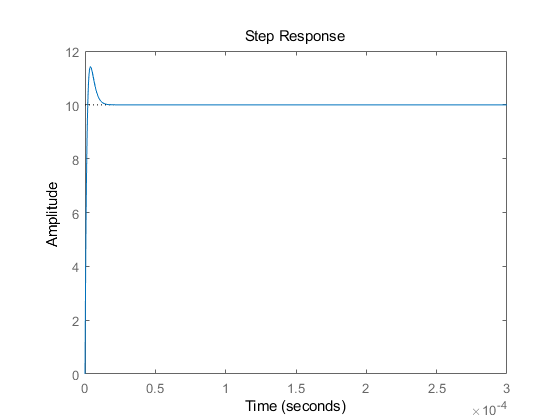

step(Hs_real,Tresp)

[stepy,stept]=step(Hs_real,Tresp);
Tsettle1=stept(find(abs(stepy/N_num-1)>0.05, 1,'last'))

Tsettle1 = 8.1067e-06

% z-domain response calc
for i=1:length(freq_rad_norm)
    Gs_jw(i,1)=subs(Gs, z, exp(1j*freq_rad_norm(i,1)));
    Gs_mag_dB(i,1)=20*log10(abs(Gs_jw(i,1)));
    Gs_ang_deg(i,1)=angle(Gs_jw(i,1))/pi*180;
    
    Hs_jw(i,1)=subs(Hs, z, exp(1j*freq_rad_norm(i,1)));
    Hs_mag_dB(i,1)=20*log10(abs(Hs_jw(i,1)));
    Hs_ang_deg(i,1)=angle(Hs_jw(i,1))/pi*180;
end
Gs_mag_dB=double(Gs_mag_dB);
Gs_ang_deg=double(Gs_ang_deg);
fprintf('Loop Gain K=%1.2g Hz\n',double(K)/2/pi*fref_num);

Loop Gain K=1.6e+05 Hz


fprintf('Unity Gain Freq.: %1.2g Hz\n', freq(find(Gs_mag_dB>=0, 1, 'last' )));

Unity Gain Freq.: 1.6e+05 Hz


%fprintf('Zero freq.Z=%1.2g Hz\n',1/tz1/(2*pi));
PM=Gs_ang_deg(find(Gs_mag_dB>=0, 1, 'last' ))-(-180);
fprintf('Phase Margin(deg): %1.1fC\n',PM);

Phase Margin(deg): 74.3C


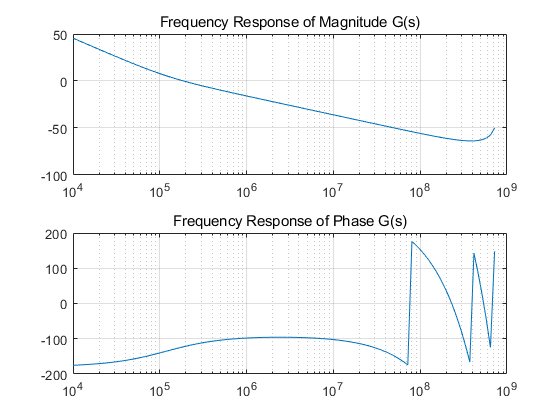


figure(1);
subplot(2,1,1),semilogx(freq,Gs_mag_dB); grid on; title('Frequency Response of Magnitude G(s)');
subplot(2,1,2),semilogx(freq,Gs_ang_deg); grid on; title('Frequency Response of Phase G(s)');

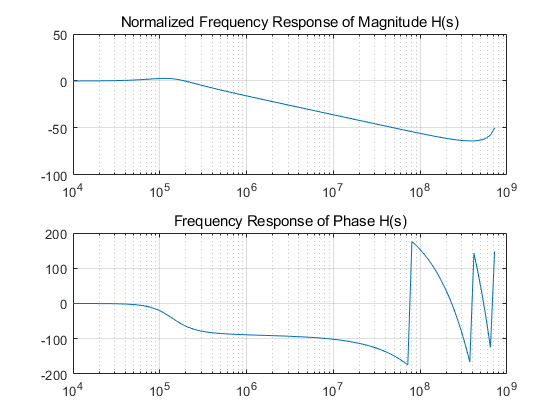


figure(2);
subplot(2,1,1),semilogx(freq,Hs_mag_dB-20*log10(N_num)); grid on; title('Normalized Frequency Response of Magnitude H(s)');
subplot(2,1,2),semilogx(freq,Hs_ang_deg); grid on; title('Frequency Response of Phase H(s)');